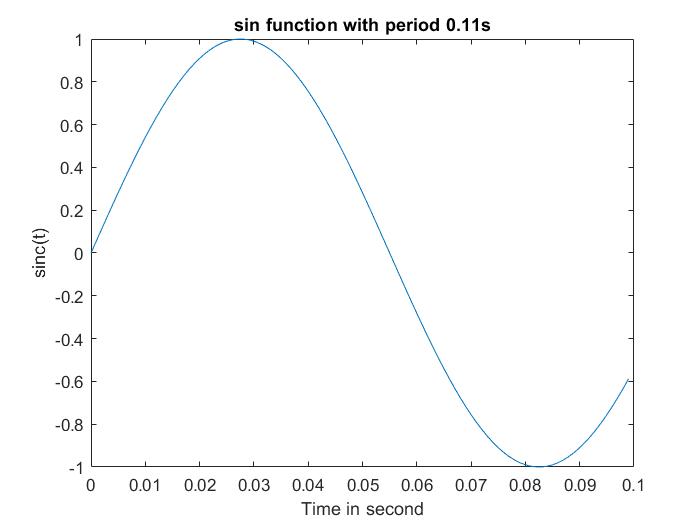

clear all;
close all;
clc;

L = 100;
Fs = 1000; % Sampling frequency.
n = [0:L-1];
t = n/Fs;
T = 0.11;
% T = 0.011;
% T = 0.005;  
x = sin(2*pi*t/T);
plot(t,x);
xlabel('Time in second');
ylabel('sinc(t)');
title('sin function with period 0.11s');

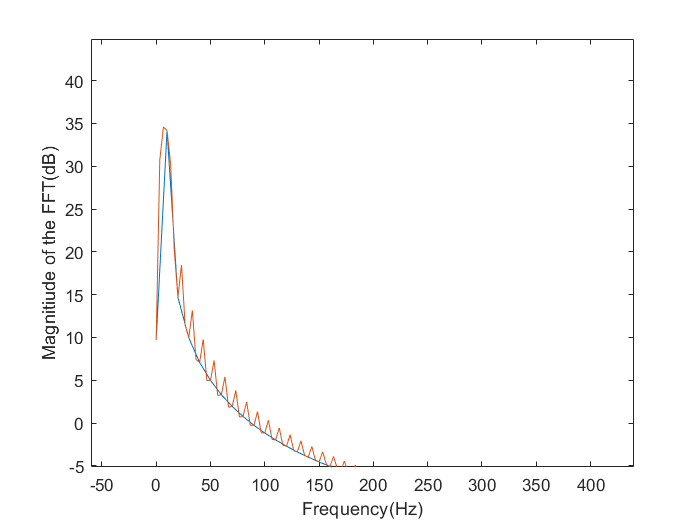


% fmagplot(x, 1e-3)
fmagplot_02(x, 1/Fs);
hold on;

xp = [x, zeros(1,200)];
% fmagplot(xp, 1e-3);
fmagplot_02(xp, 1/Fs);

function fmagplot_02(x, dt)
Xw = fft(x);
L = length(x);
range = 0:L/2;
ff = range/L/dt;
plot(ff,mag2db(abs(Xw(1+range))));
xlabel('Frequency(Hz)');
ylabel('Magnitiude of the FFT(dB)');
end

function fmagplot_01(xa,dt) 
L = length(xa);
Nfft = 2.^ceil(log2(L));
Xa = fft(xa,Nfft);  
range = 0:(Nfft / 4);

ff = range/Nfft/dt;

plot(ff,abs(Xa(1+range)));
title('Continuous-Time Fourier transform (MAG)');
xlabel('Frequency (Hz)');
grid
end